# Tutorial of the Unbiased Competition Model

This tutorial demonstrates how to implement the resonant network model used in  [Sherfey, Ardid et al. 2018](https://doi.org/10.1371/journal.pcbi.1006357).

- **Goals**: 

- llustrate the creation and usage of DynaSim models endowed with multi-compartment neurons and mechanisms specified by the user. It is recommended that you complete the UnbiasedCompetition tutorial first.

- Show how to modify the dynamics of a model, the resonant network model in this case, by tuning its internal parameters.

- **Structure**: After a brief introduction, the first sections in the tutorial show how to load `DynaSim` and set up the model. The execution of the model is done in section Run the simulation.  Visualization of the results is explained in section Visualize the results.

- **Reference:**

- Sherfey J. S., Ardid S., Hass J., Hasselmo M., & Kopell N. J. (2018). [Flexible resonance in prefrontal networks with strong feedback inhibition.](https://doi.org/10.1371/journal.pcbi.1006357) *PLoS Computational Biology*, 14(8): e1006357.

## Background

We conceptualize network resonance as a peak amplitude in the time- and population-averaged firing rates for different cell types in a network of neurons.

## Load DynaSim

If you haven't loaded DynaSim, do it.

dynasim_path = '../../..';
addpath(genpath(dynasim_path));

## Implementation

In this section we specify the initial settings both of the simulation (how and for how long we integrate the model) and that of the model itself (all its mechanisms and their parameters).

### Simulation parameters

In this section we specify the integration parameters: the integration time step (dt), the solver that we will be using (e.g., rk4), the duration of the simulation, an initial onset time (different than 0 if wanted), and the transient time (which is used to ensure that dynamics is not affected by the initial conditions).

%% Simulation time definition
dt = 0.01           % Integration time step

dt = 0.0100

solver =  'euler'      % Integration solver

solver = 'euler'

duration = 1000     % Simulation duration

duration = 1000

tOn = 0;                           % Initial time onset
tspan = [tOn,tOn+duration];        % Simulation interval
transient = 250    % Transient time

transient = 250

### Model specification

We start defining populations for each cell type in the larger model. We will take advantage of a function that specifies single-cell models (including the ordinary differential equations (ODEs)) and then combine them into a larger specification structure for the cortical network. Later on, we will update details of the network connectivity and inputs driving the network. 

% Single layer PFC model size
Ne=8;  % # pyramidal cells
Nfs=2; % # fast-spiking (FS) cells
Nrs=2; % # regular-spiking non-pyramidal (RSNP) cells

% -------------------------------------------------------------------------
% Specify populations: Custom cell models (see also: 'help get_PFC_cell')
% -------------------------------------------------------------------------
% Two-compartment Pyramidal cell model ('Es'=soma, 'Ed'=dendrite)
spec=get_PFC_cell('DS02PYjs',Ne);
% One-compartment FS model ('FS' = PV+ interneuron inhibiting PY soma)
spec.populations(end+1)=getfield(get_PFC_cell('DS02FSjs',Nfs),'populations');
% One-compartment RSNP model ('RSNP' = CB+ interneuron inhibiting PY dendrite)
spec.populations(end+1)=getfield(get_PFC_cell('DS02RSNPjs',Nrs),'populations');


### Parameters of recurrent synaptic connections

Here, we override the default mechanisms and parameters of the connections between all cortical cell types. 

% -------------------------------------------------------------------------
% Specify network connections (all-to-all)
% -------------------------------------------------------------------------
% [DS02,DG07]: AMPA (taur=.2,taud=1,E=0), NMDA (taur=2.3,taud=95,E=0), GABA (taur=.5,taud=5,E=-75)
tauAMPAr=.2;  % ms, AMPA rise time
tauAMPAd=1;   % ms, AMPA decay time
tauNMDAr=2.3; % ms, NMDA rise time
tauNMDAd=95;  % ms, NMDA decay time
tauGABAr=.5;  % ms, GABAa rise time
tauGABAd=5;   % ms, GABAa decay time
% [DS02]:
Npc=100;  % # principal cells in original [DS02] publication
Nin=37;   % # interneurons in original [DS02] publication
gAMPAee=3e-3;       % uS, PY->PY, maximal AMPA conductance
gNMDAee=gAMPAee/50; % uS, PY->PY, maximal NMDA conductance
gGABAie=.2e-3;      % uS, FS->PY, maximal GABAa conductance
gAMPAei=.74e-3;     % uS, PY->IN
gNMDAei=gAMPAei/50; % uS, PY->IN
gGABAii=.6e-3;      % uS, FS->IN

% [D97] DeFelipe, J. (1997). Types of neurons, synaptic connections and chemical characteristics of cells immunoreactive for calbindin-D28K, parvalbumin and calretinin in the neocortex. Journal of chemical neuroanatomy, 14(1), 1-19.
% - NMDA colocalizes with PV+ but not CB+
% - PV+ INs target PY soma; CB+ INs target PY dendrite
% - PV+ INs are FS; CB+ INs are RSNP or LTS
% [Traub/Whittington] (2010, in "Cortical Oscillations in Health and Disease")
% - CB+ inhibition is longer-lasting than PV+ inhibition
tauGABAdCB=13; % ms, GABAa decay time for inhibition from RSNP CB+ interneurons

% recurrent connections between pyramidal cells (add to existing intercompartmental connections)
index=find(strcmp('Es->Ed',{spec.connections.direction}),1,'first');
spec.connections(index).mechanism_list={'iAMPA','iNMDA',spec.connections(index).mechanism_list{:}};
spec.connections(index).parameters={'gAMPA',gAMPAee*Npc/Ne,'gNMDA',gNMDAee*Npc/Ne,'EAMPA',0,'ENMDA',0,...
  'tauAMPAr',tauAMPAr,'tauAMPA',tauAMPAd,'tauNMDAr',tauNMDAr,'tauNMDA',tauNMDAd,spec.connections(index).parameters{:}};
% pyramidal<->FS connections
spec.connections(end+1).direction='Es->FS';
spec.connections(end).mechanism_list={'iAMPA','iNMDA'};
spec.connections(end).parameters={'gAMPA',gAMPAei*Npc/Ne,'gNMDA',gNMDAei*Npc/Ne,'EAMPA',0,'ENMDA',0,...
  'tauAMPAr',tauAMPAr,'tauAMPA',tauAMPAd,'tauNMDAr',tauNMDAr,'tauNMDA',tauNMDAd};
spec.connections(end+1).direction='FS->Es';
spec.connections(end).mechanism_list={'iGABA'};
spec.connections(end).parameters={'gGABA',gGABAie*Nin/Nfs,'tauGABAr',tauGABAr,'tauGABA',tauGABAd,'EGABA',-75};
% pyramidal<->RSNP connections
spec.connections(end+1).direction='Es->RSNP';
spec.connections(end).mechanism_list={'iAMPA'};
spec.connections(end).parameters={'gAMPA',gAMPAei*Npc/Ne,'EAMPA',0,'tauAMPAr',tauAMPAr,'tauAMPA',tauAMPAd};
spec.connections(end+1).direction='RSNP->Ed';
spec.connections(end).mechanism_list={'iGABA'};
spec.connections(end).parameters={'gGABA',gGABAie*Nin/Nrs,'tauGABAr',tauGABAr,'tauGABA',tauGABAdCB,'EGABA',-75};
% interneuron<->interneuron connections
spec.connections(end+1).direction='FS->FS';
spec.connections(end).mechanism_list={'iGABA'};
spec.connections(end).parameters={'gGABA',gGABAii*Nin/Nfs,'tauGABAr',tauGABAr,'tauGABA',tauGABAd,'EGABA',-75};
spec.connections(end+1).direction='RSNP->RSNP';
spec.connections(end).mechanism_list={'iGABA'};
spec.connections(end).parameters={'gGABA',gGABAii*Nin/Nrs,'tauGABAr',tauGABAr,'tauGABA',tauGABAdCB,'EGABA',-75};
spec.connections(end+1).direction='FS->RSNP';
spec.connections(end).mechanism_list={'iGABA'};
spec.connections(end).parameters={'gGABA',gGABAii*Nin/Nfs,'tauGABAr',tauGABAr,'tauGABA',tauGABAd,'EGABA',-75};
spec.connections(end+1).direction='RSNP->FS';
spec.connections(end).mechanism_list={'iGABA'};
spec.connections(end).parameters={'gGABA',gGABAii*Nin/Nrs,'tauGABAr',tauGABAr,'tauGABA',tauGABAdCB,'EGABA',-75};


### Parameters of external Poisson synaptic inputs from PFC

Here, we similarly override the default ODEs and inputs to the target population in the PFC model. The new input defined below uses functions getPopRhythmGating and getPoissonGating to generate periodic and nonperiodic Poisson spike trains. We start setting the random seed for the Poisson generator. Next, we define the new ODEs for the target population. After that, we update the default parameters for the input, group them into cell arrays that facilitate the modification of the default specification.

%% update inputs (background poisson + rhythmic population signal)

% randomize seed for Poisson input
rng('shuffle'); 
seed=getfield(rng,'Seed');

TargetPop='Ed'; % name of population(s) to stimulate (for inputs and recurrent connections Es->Ed)
OutputPop='Es'; % name of population to analyze (for post-simulation analysis)
EiPop='Es';     % excitatory population input compartment for E/I connectivity
EoPop='Es';     % excitatory population output compartment for E/I connectivity
IPop='FS';      % inhibitory population input=output compartment for E/I connectivity

TargetPopIndex=find(strcmp(TargetPop,{spec.populations.name}));
OutputPopIndex=find(strcmp(OutputPop,{spec.populations.name}));
IPopIndex=find(strcmp(IPop,{spec.populations.name}));

% generic inputs and dependent state equations
input_def={'input(V)=iNoise(V)+iSignal(V)+iPoisson(V); monitor input,ginput,iNoise,iSignal,iPoisson; onset=400; offset=inf;';
           'ginput(t)=gNoise.*sNoise(k,:)+gSignal.*sSignal(k,:)+gPoisson.*sPoisson(k,:);';
           'iNoise(V)=gNoise.*sNoise(k,:).*(V-0); gNoise=.001; dcNoise=5000;';
           'iSignal(V)=gSignal.*sSignal(k,:).*(V-0); gSignal=.02;';
           'iPoisson(V)=gPoisson.*sPoisson(k,:).*(V-0); gPoisson=0;';           
           'sNoise=getPopRhythmGating(1,Npop,0,dcNoise,0,0,T,0,inf,2,1,seed);';
           'sSignal=getPopRhythmGating(Ninputs,Npop,pSignal,rSignal,fSignal,wSignal,T,onset,offset,tauSignal,1,seed,ones(1,Npop),actype);';
           'sPoisson=getPoissonGating(0,rSignal*Ninputs,rSignal*Ninputs,fSignal,0,onset,offset,tauSignal,T,Npop,ones(1,Npop));';
           'rSignal=5; wSignal=5; fSignal=32; pSignal=1; tauSignal=2; Ninputs=100; seed=0; actype=''step'';';
           };
state_equations=['dV/dt=(@current-input(V)+Iapp*(t>onset&t<offset))./Cm; Cm=1; Iapp=0; V(0)=-65;' input_def{:}];

% common signal parameters
Ninputs=100; % # of simulated input cells
onset=400;
offset=inf;
% E-cell inputs
% noise:
gNoiseE=.0007;
dcNoiseE=1000; % spk/s, independent homogeneous Poisson (e.g., 1000 cells at 5 spk/s)
% signal:
gSignalE=.0015;
pSignalE=0;  % probability that input i connects to target j (set to 0 for independent inputs)
wSignalE=1; % ms, synchrony of population spikes on a given cycle
fSignalE=25; % Hz, population frequency
rSignalE=10; % spk/s, average cell firing rate
tauSignalE=2; % ms, synaptic decay constant
% FS-cell inputs
% noise:
gNoiseI=.001;
dcNoiseI=0; % spk/s, independent homogeneous Poisson (e.g., 1000 cells at 5 spk/s)
% signal:
gSignalI=0;
pSignalI=0;  % probability that input i connects to target j (set to 0 for independent inputs)
wSignalI=1; % ms, synchrony of population spikes on a given cycle
fSignalI=25; % Hz, population frequency
rSignalI=0; % spk/s, average cell firing rate
tauSignalI=2; % ms, synaptic decay constant

% collect input and biophysical parameters
E_input_parameters ={'Ninputs',Ninputs,'onset',onset,'offset',offset,'gSignal',gSignalE,'rSignal',rSignalE,'wSignal',wSignalE,'fSignal',fSignalE,'pSignal',pSignalE,'tauSignal',tauSignalE,'gNoise',gNoiseE,'dcNoise',dcNoiseE,'gPoisson',0,'seed',seed};
I_input_parameters ={'Ninputs',Ninputs,'onset',onset,'offset',offset,'gSignal',gSignalI,'rSignal',rSignalI,'wSignal',wSignalI,'fSignal',fSignalI,'pSignal',pSignalI,'tauSignal',tauSignalI,'gNoise',gNoiseI,'dcNoise',dcNoiseI,'gPoisson',0,'seed',seed};

% update population specification (add inputs and input parameters)
warning off
spec=dsApplyModifications(spec,{TargetPop,'equations',state_equations}); % Ed
spec.populations(TargetPopIndex).parameters=cat(2,E_input_parameters,dsRemoveKeyval(spec.populations(TargetPopIndex).parameters,E_input_parameters(1:2:end)));
spec=dsApplyModifications(spec,{IPop,'equations',state_equations}); % FS
spec.populations(IPopIndex).parameters=cat(2,I_input_parameters,dsRemoveKeyval(spec.populations(IPopIndex).parameters,I_input_parameters(1:2:end)));

## Run the simulation

Once the model is properly specified, we proceed to run the simulation according to the simulation parameters and model specification. For this we use the 'vary' argument in DynaSim, so we can run a set of simulations in 1 call. Specfically, we vary the frequency of the periodic drive to the dendritic compartment of the pyramidal cells.  This set of simulations enables us to explore the effect of resonance in the network.

% drive network with different frequencies
vary = {'Ed','fSignal',0:5:50};
tspan = [0 1000];  % [beg end], ms
dt = .01;         % fixed time step, ms
compile_flag = 0; % whether to compile simulation
verbose_flag = 0; % whether to display verbose logs
solver_options = {'tspan',tspan,'solver','rk1','dt',dt,'compile_flag',compile_flag,'verbose_flag',verbose_flag};
data = dsSimulate(spec,'vary',vary,solver_options{:});


## Visualize the results

Finally, we display the time-averaged firing rates for each population versus the driving frequency to the pyramidal cells. We select only the post-stimulus interval using dsSelect before calling the function dsPlotFR which performs the analysis internally on all of the populations in the data structure. Note the firing rate peaks for all cell types when the network is driven by a 30Hz input.

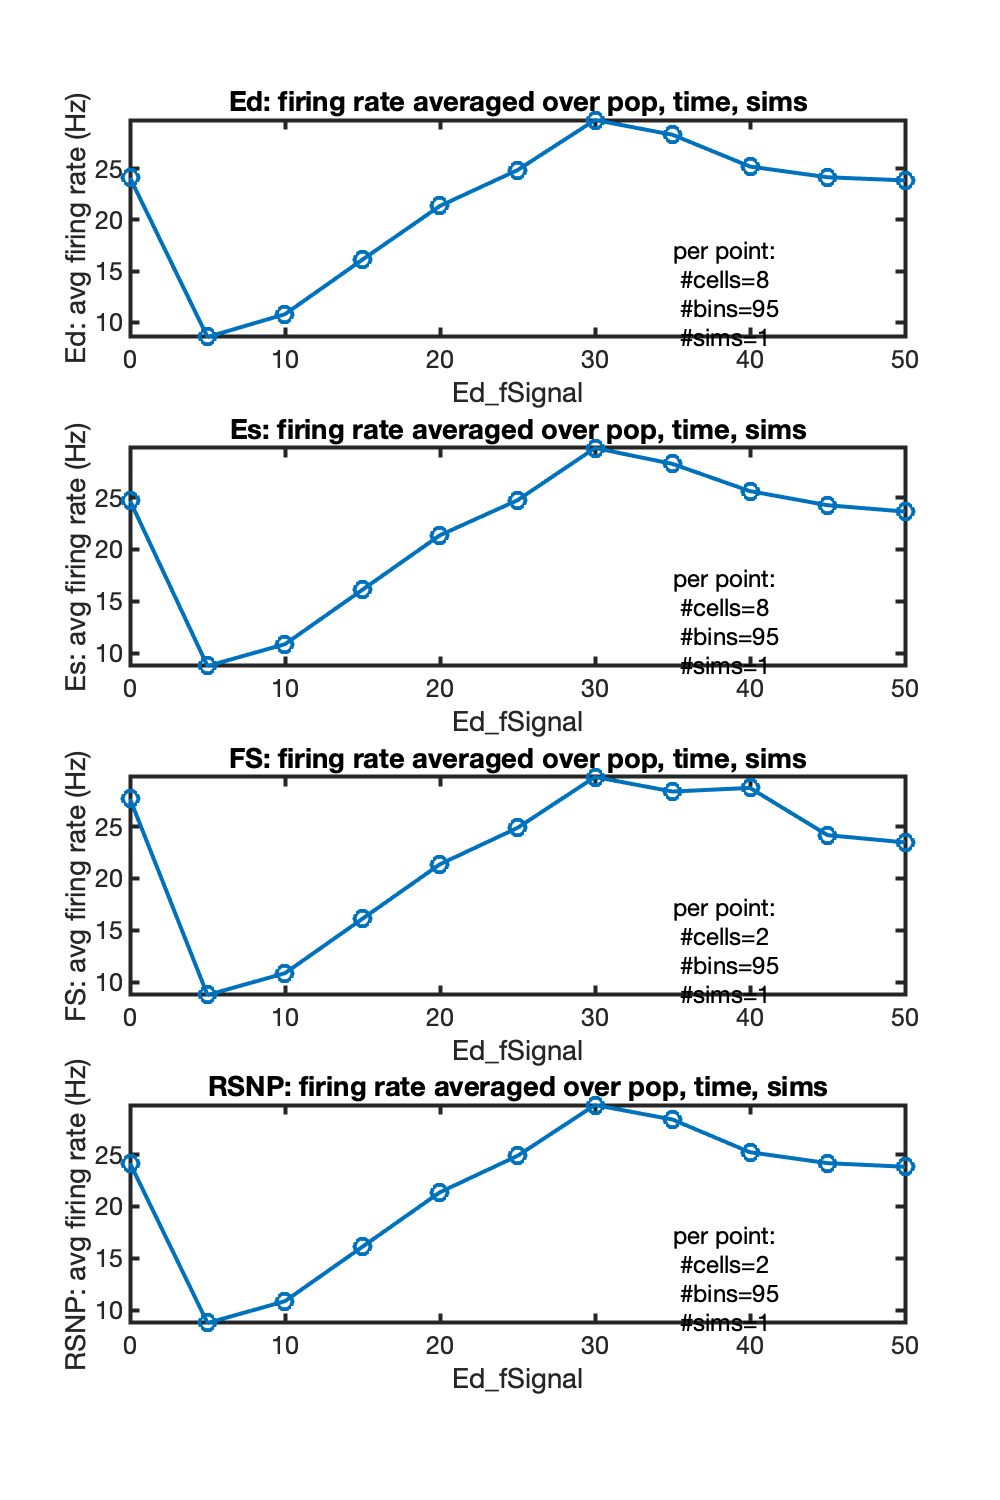

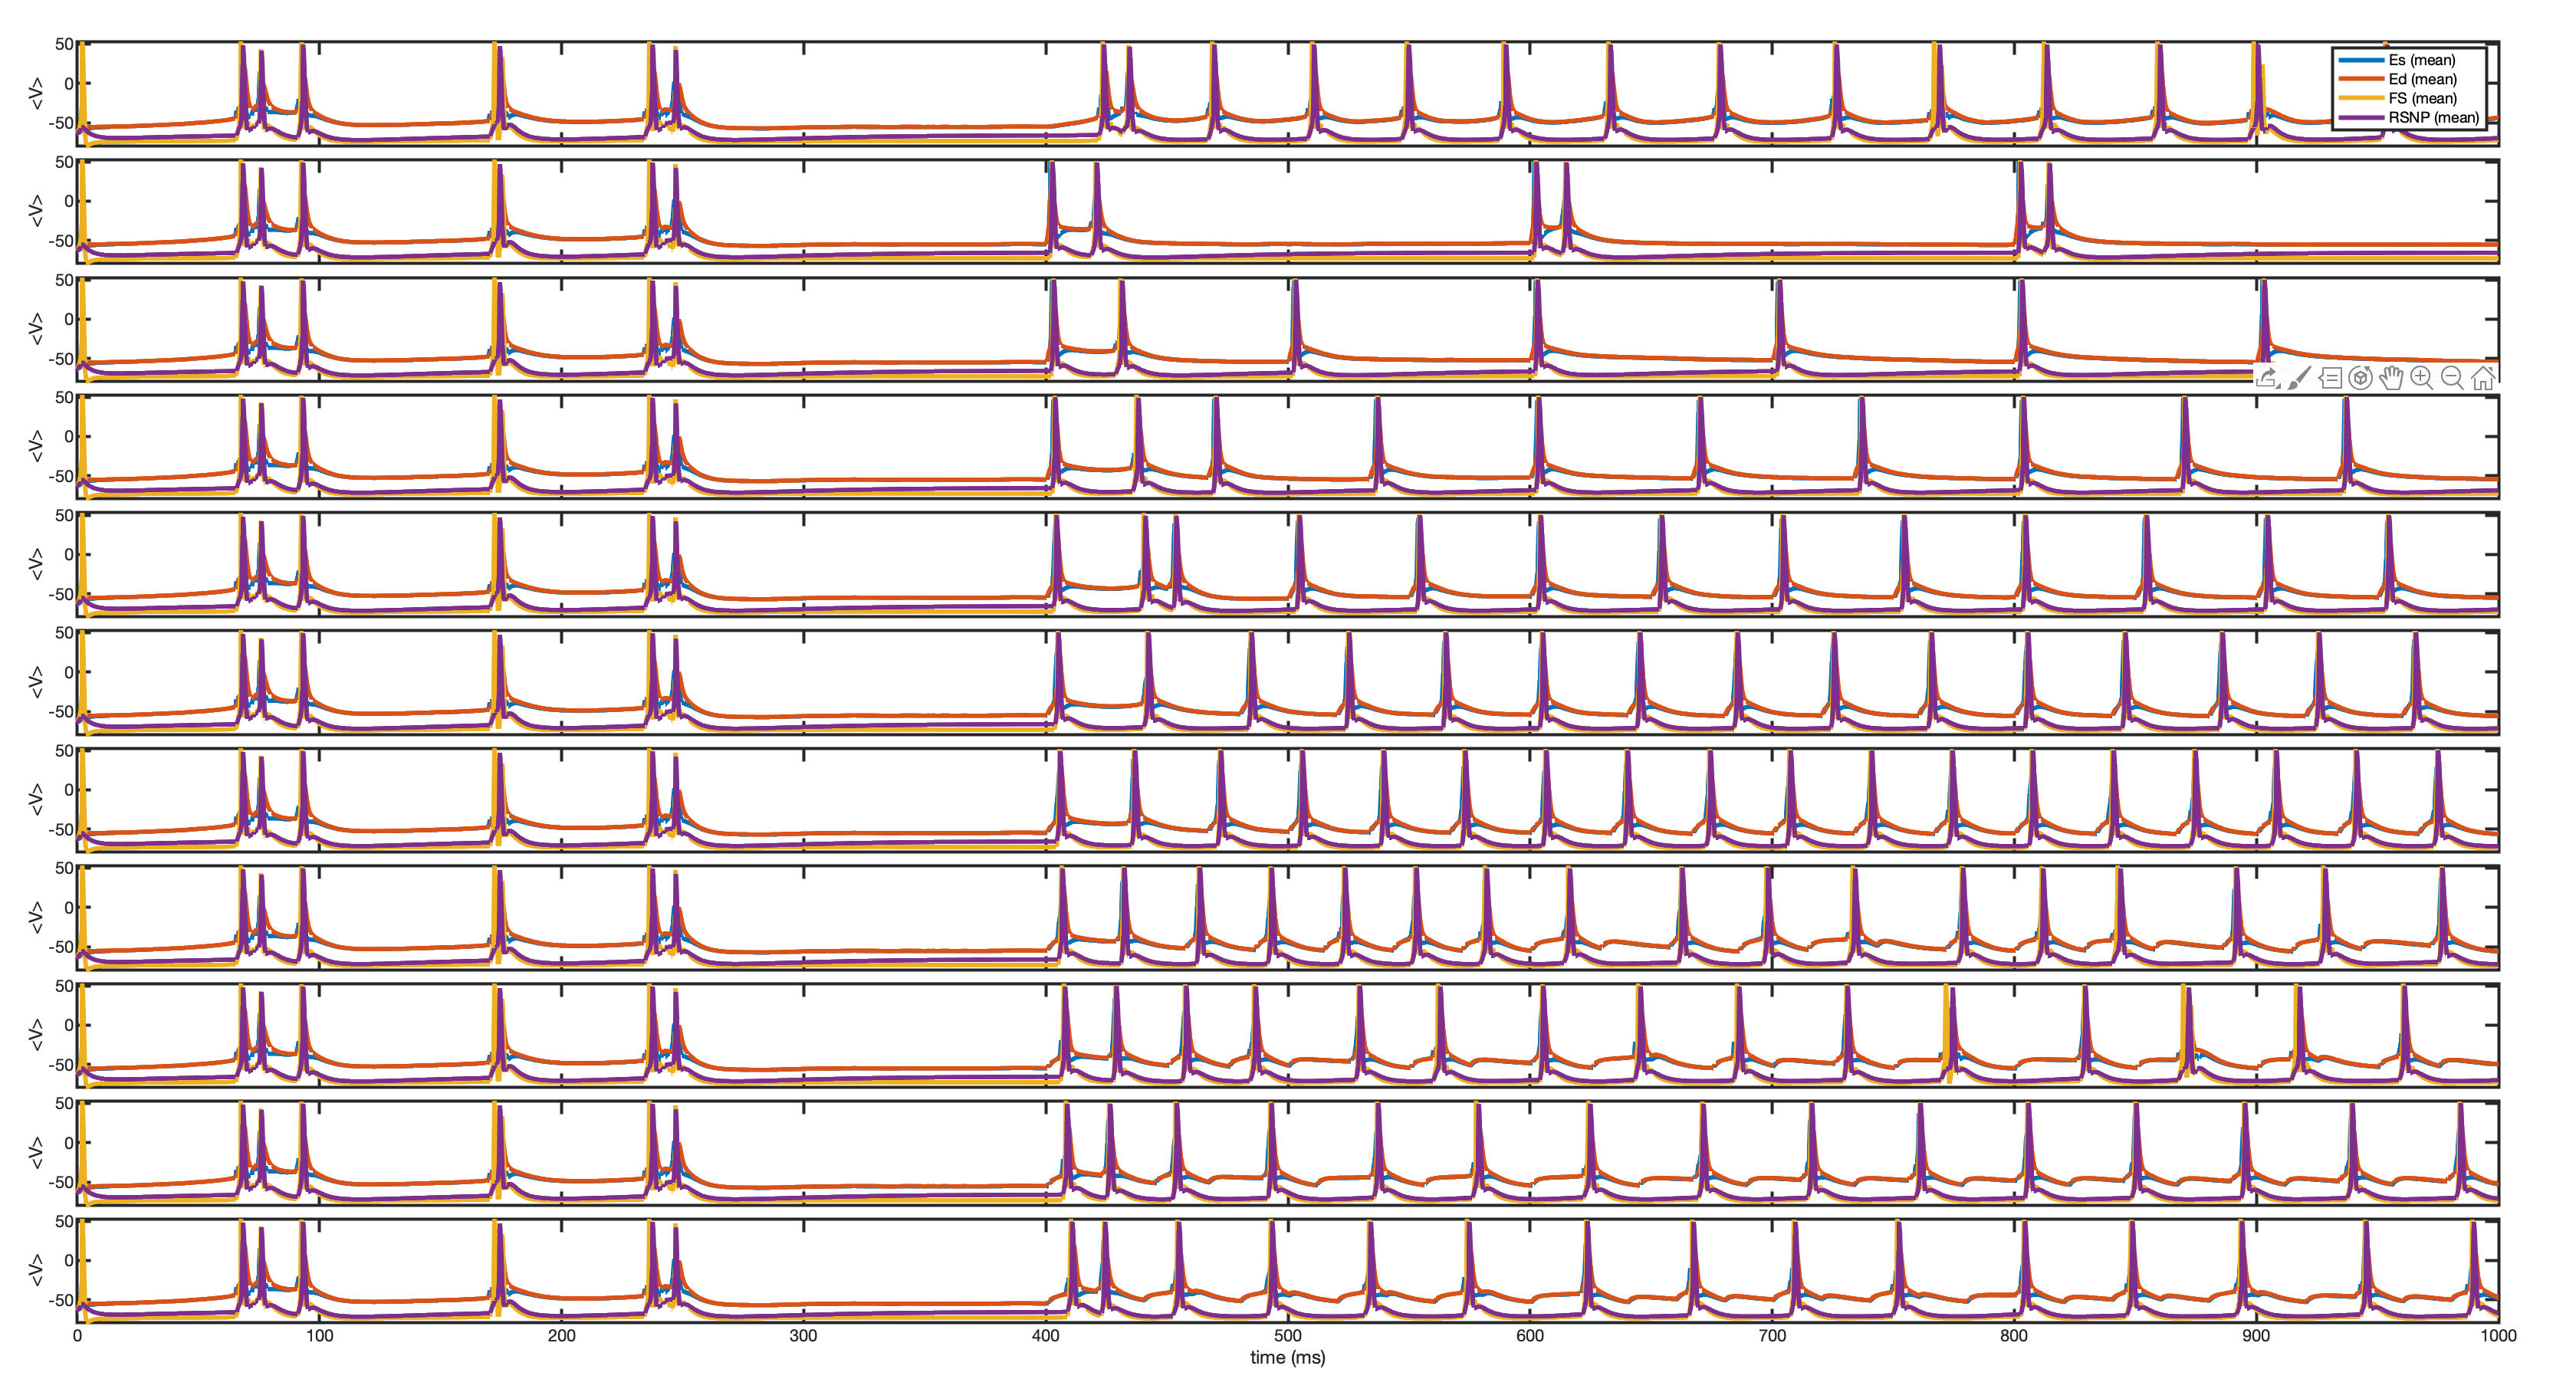

% plot mean firing rate vs. varied parameter (input frequency)
select_data = dsSelect(data,'time_limits',[onset, tspan(2)]);
dsPlotFR(select_data);

% Population-mean voltage traces
dsPlot(data,'plot_type','waveform');